clc,clear,close all


    K     = 3;                                            % Cluster Numbers: for this application,
%the number of clusters is set to three for Cup/Disc, retina, and black
%masks. However, this setting doesn't guarentee that Optical Disc can be picked up
%every run. So multiple runs were required.
    Ite   = 10;                                           % K-means Iteration
    bw   = 0.05;                                           % Mean Shift Bandwidth
    
for i=3:102


i = 12

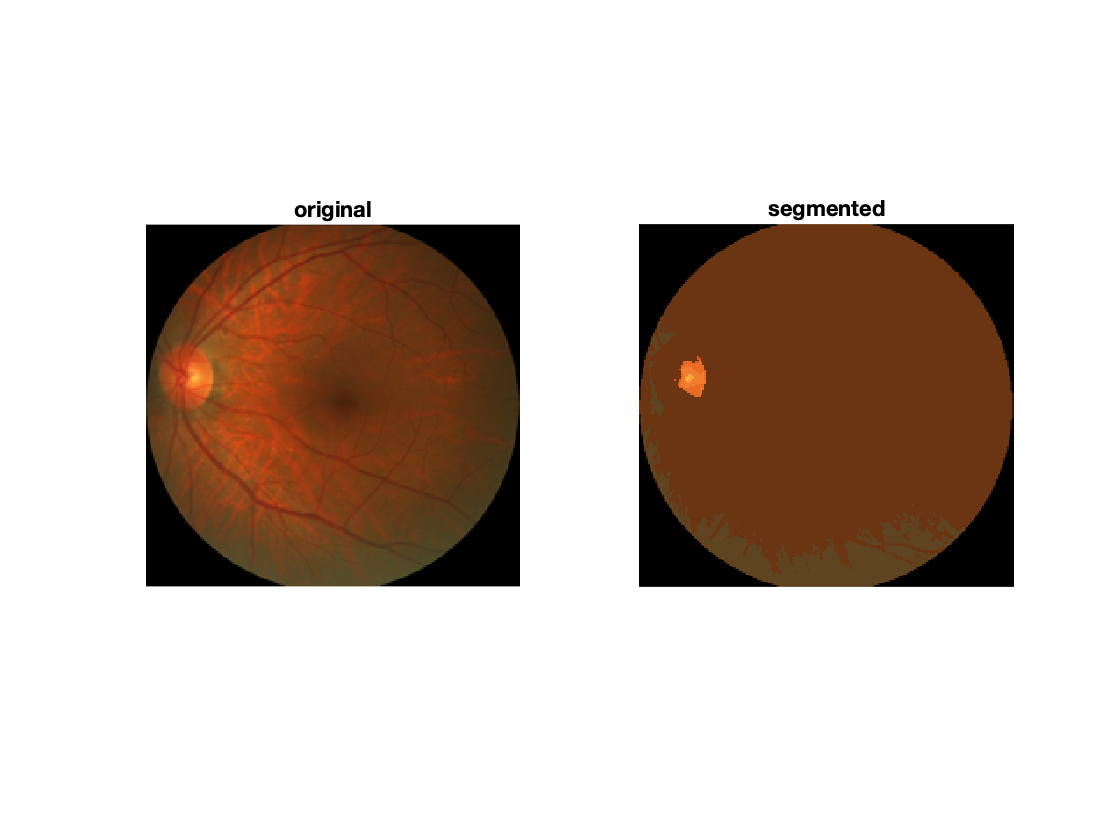

ImageLts=dir('./images');
TruthLts=dir('./truth/');

    Image_Dir=fullfile(ImageLts(i).folder,ImageLts(i).name);
    Truth_Dir=fullfile(TruthLts(i).folder,TruthLts(i).name);

    I = im2double(imread(Image_Dir));                    % Load Image
    I=imresize(I, 0.1);
    Truth=imread(Truth_Dir);
    Truth=imresize(Truth, 0.1);
    Fea = reshape(I,size(I,1)*size(I,2),3);                 % Color Features

  
    T_k=KMean(I,Fea,K,Ite);
    T_k=double(int8(T_k(:,:,1)));

    ANS1=dice(T_k,double(Truth));
    Dice_KM(i-2)=ANS1(1);

    [T_m,]=MShift(I,bw);    

    T_m=double(int8(T_m(:,:,1)));

    ANS2=dice(T_m,double(Truth));
    Dice_MS(i-2)=ANS2(1);
end